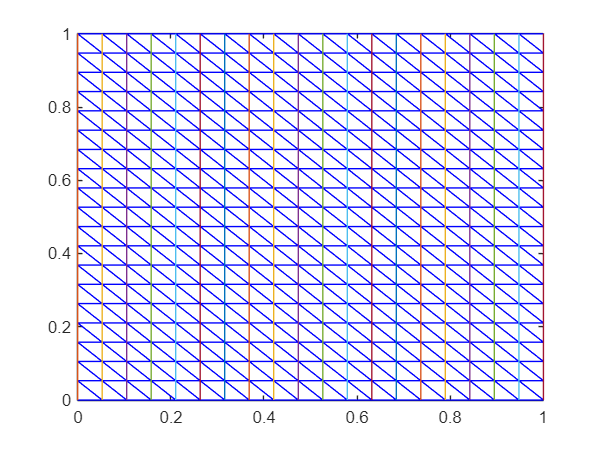



% --- Demo script: build a simple triangulation, mark vertices, visualize clusters ---
% 1) Build a 2D triangulated grid (replace this with your own V, TRIP if available)
nx = 20; ny = 20;
[X,Y] = meshgrid(linspace(0,1,nx), linspace(0,1,ny));
V = [X(:) Y(:)];                     % vertex coordinates (n-by-2)
DT = delaunayTriangulation(V);
TRIP = DT.ConnectivityList;          % triangles (T-by-3, 1-based indices)

triplot(DT,X,Y);


% 2) Choose a marked set containing two separated regions
c1 = [0.25 0.25]; r1 = 0.18;
c2 = [0.75 0.75]; r2 = 0.14;
idx1 = find(vecnorm(V - c1, 2, 2) < r1);
idx2 = find(vecnorm(V - c2, 2, 2) < r2);
ORIGINALVERTICES = unique([idx1; idx2]);


% 3) Compute clusters using the third option
clusters = clustersFromTripScanning(TRIP, ORIGINALVERTICES);

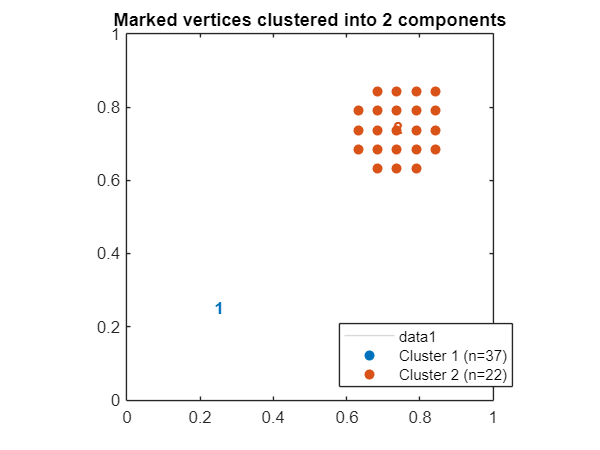


% 4) Visualize: mesh edges + marked vertices colored by cluster
figure; clf;
is3D = (size(V,2) == 3);
if ~is3D
    triplot(TRIP, V(:,1), V(:,2), 'Color', [0.85 0.85 0.85]);
    hold on;
else
    patch('Faces',TRIP,'Vertices',V, ...
          'FaceColor',[0.95 0.95 0.95], 'EdgeColor',[0.8 0.8 0.8]);
    hold on; view(3);
end
axis equal; axis tight; box on;
title(sprintf('Marked vertices clustered into %d components', numel(clusters)));

% Color each cluster differently
C = lines(max(numel(clusters), 1));  % colormap
for k = 1:numel(clusters)
    ids = clusters{k};
    if ~is3D
        scatter(V(ids,1), V(ids,2), 36, C(k,:), 'filled', ...
                'DisplayName', sprintf('Cluster %d (n=%d)', k, numel(ids)));
        % Label cluster centroid for clarity
        c = mean(V(ids,:), 1);
        text(c(1), c(2), sprintf('%d', k), 'Color', C(k,:), ...
             'FontWeight', 'bold', 'HorizontalAlignment', 'center');
    else
        scatter3(V(ids,1), V(ids,2), V(ids,3), 36, C(k,:), 'filled', ...
                 'DisplayName', sprintf('Cluster %d (n=%d)', k, numel(ids)));
    end
end
legend('Location','best'); hold off;


% 5) Optional: print cluster contents/sizes
for k = 1:numel(clusters)
    fprintf('Cluster %d: %d vertices\n', k, numel(clusters{k}));
end

Cluster 1: 37 vertices
Cluster 2: 22 vertices


How to use with your own data:

- Set V to your vertex coordinate matrix (n-by-2 for planar, or n-by-3 for 3D).

- Set TRIP to your triangle connectivity (T-by-3, 1-based indices).

- Set ORIGINALVERTICES to your marked vertex IDs.

- Run clusters = clustersFromTripScanning(TRIP, ORIGINALVERTICES), then run the plotting block. The marked vertices will be colored by cluster, and the title/legend will show how many components were found.

% --- Function: third option (scan TRIP to find neighbors) ---

function clusters = clustersFromTripScanning(TRIP, ORIGINALVERTICES)
    if isempty(TRIP) || size(TRIP,2) ~= 3
        error('TRIP must be a T-by-3 matrix of vertex indices.');
    end
    marked = unique(ORIGINALVERTICES(:));
    if isempty(marked)
        clusters = {};
        return;
    end
    n = max(max(TRIP(:)), max(marked));
    posInMarked = zeros(n,1);
    posInMarked(marked) = 1:numel(marked);
    visitedMarked = false(numel(marked),1);
    clusters = {};
    for idx = 1:numel(marked)
        if visitedMarked(idx), continue; end
        v = marked(idx);
        comp = v;
        visitedMarked(idx) = true;
        queue = v;
        head = 1;
        while head <= numel(queue)
            u = queue(head);
            head = head + 1;
            triRows = TRIP(any(TRIP == u, 2), :);  % triangles containing u
            neigh = unique(triRows(:));
            neigh(neigh == u) = [];
            neighPos = posInMarked(neigh);
            mask = neighPos ~= 0;          % in marked
            neigh = neigh(mask);
            neighPos = neighPos(mask);
            addMask = ~visitedMarked(neighPos);
            toAdd = neigh(addMask);
            toAddPos = neighPos(addMask);
            if ~isempty(toAdd)
                queue = [queue; toAdd]; %#ok<AGROW>
                visitedMarked(toAddPos) = true;
                comp = [comp; toAdd]; %#ok<AGROW>
            end
        end
        clusters{end+1} = comp; %#ok<AGROW>
    end
end